## Linearización de $y_{n+1} =\sqrt{y_n }$

Preparación del entorno de trabajo

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

Carga del modelo

model_name = "linearization_sqrt";
load_system(model_name)
% open_system(model_name) will also open it

Parámetros del solver

% Set solver parameters
set_param(model_name, ...
    SolverType  = "Fixed-Step", ...
    SolverName  = "FixedStepDiscrete", ...
    StartTime   = "0",...
    StopTime    = "5", ...
    FixedStep   = "1" ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Constantes del modelo

% Initial conditions
theta0 = 10;

% Global constants
% Example: g = 9.8

Simulación del modelo

simulation_data = sim(model_name, SimulationMode="normal");
% .yout contains name and outport of each signal
% .tout contains model's global timings

Extraer información (output block requerido para .yout)

signal = simulation_data.yout{1};
% .yout signals can also be accessed by {index}
signal_values = signal.Values.Data;
t_values = signal.Values.Time;

signalbus = simulation_data.yout.getElement('out')

signalbus =   Simulink.SimulationData.Signal
  Package: Simulink.SimulationData

  Properties:
              Name: 'out'
    PropagatedName: ''
         BlockPath: [1×1 Simulink.SimulationData.BlockPath]
          PortType: 'inport'
         PortIndex: 1
            Values: [1×1 struct]


  Methods, Superclasses

signalbus.Values

ans = struct with fields:
      y_n_: [1×1 timeseries]
    x_n_1_: [1×1 timeseries]


Análisis salida

[signal_max, index_max] = max(signal_values);
fprintf("La señal es máxima en t = %ds", t_values(index_max))

La señal es máxima en t = 0s

Graficar la salida

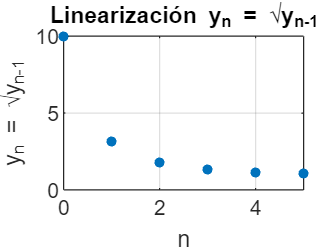

plot(t_values, signal_values, '.', MarkerSize=12)
hold on
% Documentation and settings
title('Linearización y_n = \surd{y_n-1}')
xlabel('n'); ylabel('y_n = \surd{y_n-1}');
xlim([t_values(1), t_values(end)]);
% legend('(t, theta(t))', 'Location','northeast')
grid on
hold off

## Ejercicio 13 Descomposición del plomo

Preparación del entorno de trabajo

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

Carga del modelo

model_name = "Ejer13_DescomposicionPlomo";
load_system(model_name)
% open_system(model_name) will also open it

Parámetros del solver

% Set solver parameters
set_param(model_name, ...
    SolverType  = "Fixed-Step", ...
    SolverName  = "FixedStepDiscrete", ...
    StartTime   = "0",...
    StopTime    = "50", ...
    FixedStep   = "1" ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Constantes del modelo

% Initial conditions
A0 = 50;
B0 = 7; 

% Global constants
% Example: g = 9.8

Simulación del modelo

simulation_data = sim(model_name, SimulationMode="normal");
% .yout contains name and outport of each signal
% .tout contains model's global timings

Extraer información (output block requerido para .yout)

signalA = simulation_data.yout.getElement("A_n");
% .yout signals can also be accessed by {index}
signalA_values = signalA.Values.Data;
tA_values = signalA.Values.Time;

signalB = simulation_data.yout.getElement("B_n");
signalB_values = signalB.Values.Data;
tB_values = signalB.Values.Time;

Análisis salida

% [signal_max, index_max] = max(signal_values);
% fprintf("La señal es máxima en t = %ds", t_values(index_max))

Graficar la salida

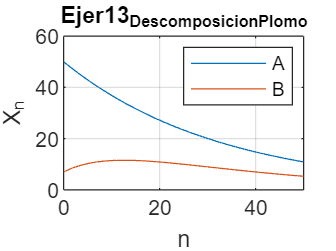

plot(tA_values, signalA_values, '-', MarkerSize=12)
hold on
plot(tB_values, signalB_values, '-', MarkerSize=12)
% Documentation and settings
title(model_name)
xlabel('n'); ylabel('{X_n}');
xlim([tA_values(1), tA_values(end)]);
legend('A', 'B', 'Location','northeast')
grid on
hold off

Planteamiento

P0 = 76kg

x = calorias por semana

P_n+1 = P_n - 0.03 * P_n - 0.1

52 semanas

Preparación del entorno de trabajo

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

Carga del modelo

model_name = "Ejer15_PesoIdeal";
load_system(model_name)
% open_system(model_name) will also open it

Parámetros del solver

% Set solver parameters
set_param(model_name, ...
    SolverType  = "Fixed-Step", ...
    SolverName  = "FixedStepDiscrete", ...
    StartTime   = "0",...
    StopTime    = "52", ...
    FixedStep   = "1" ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Constantes del modelo

% Initial conditions
P0 = 10;

% Global constants
metabolismo = 0.03  % 3%

metabolismo = 0.0300

ejercicio = 0.1 % kg

ejercicio = 0.1000

Simulación del modelo

simulation_data = sim(model_name, SimulationMode="normal");
% .yout contains name and outport of each signal
% .tout contains model's global timings

Extraer información (output block requerido para .yout)

signal = simulation_data.yout{1};
% .yout signals can also be accessed by {index}
signal_values = signal.Values.Data;
t_values = signal.Values.Time;

Análisis salida

% [signal_max, index_max] = max(signal_values);
% fprintf("La señal es máxima en t = %ds", t_values(index_max))

Graficar la salida

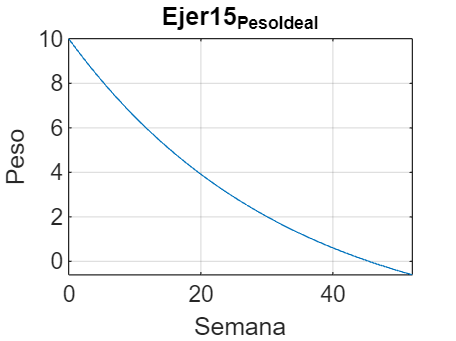

plot(t_values, signal_values, '-', MarkerSize=12)
hold on
% Documentation and settings
title(model_name)
xlabel('Semana'); ylabel('Peso');
xlim([t_values(1), t_values(end)]);
% legend('(t, theta(t))', 'Location','northeast')
grid on
hold off

### Ejercicio 18

Planteamiento

Preparación del entorno de trabajo

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

Carga del modelo

model_name = "Ejer18_EcuacionesCremona";
load_system(model_name)
% open_system(model_name) will also open it

Parámetros del solver

% Set solver parameters
set_param(model_name, ...
    SolverType  = "Fixed-Step", ...
    SolverName  = "FixedStepDiscrete", ...
    StartTime   = "0",...
    StopTime    = "20", ...
    FixedStep   = "1" ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Constantes del modelo

% Initial conditions
x1_ini = [0.1, 0.2, 0.5, 0.6];
x2_ini = [0.1, 0.2, 0.5, 0.6];
% x1_ini = 0.1;
% x2_ini = 0.1;
% Global constants
a = 1.328;

Simulación del modelo

simulation_data = sim(model_name, SimulationMode="normal");
% .yout contains name and outport of each signal
% .tout contains model's global timings

Extraer información (output block requerido para .yout)

signal1 = simulation_data.yout.getElement('x1_k');
% .yout signals can also be accessed by {index}
signal1_values = signal1.Values.Data;
t1_values = signal1.Values.Time;

signal2 = simulation_data.yout.getElement('x2_k');
% .yout signals can also be accessed by {index}
signal2_values = signal2.Values.Data;
t2_values = signal2.Values.Time;

Análisis salida

% [signal_max, index_max] = max(signal_values);
% fprintf("La señal es máxima en t = %ds", t_values(index_max))

Graficar la salida

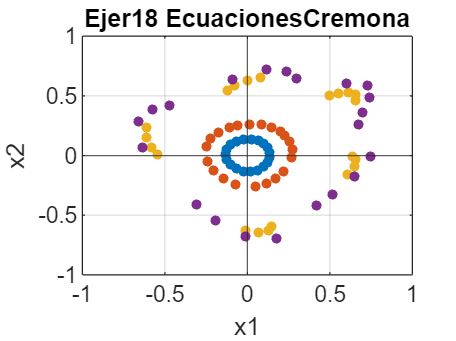

plot(signal1_values, signal2_values, '.', MarkerSize=12)
hold on
%plot(t2_values, signal2_values, '.', MarkerSize=12)
% Documentation and settings
title(strrep(model_name, '_', ' '))
xlabel('x1'); ylabel('x2');
%xlim([t1_values(1), t1_values(end)]);
xline(0); yline(0);
%legend('x1', 'Location','northeast')
grid on
hold off